Lab 1

% question-1
% gauss jacobi method

clc
clear
clf

A = [9,2,1,1;1,-9,2,1;2,1,5,1;0,1,2,9];
b = [7;-2;14;14];
x0 = [1;1;1;1];

N = 100;
errorlimit = 1e-6;
n = size(A,1);
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);
T = inv(D)*(L+U);
c = inv(D)*b;

for i=1:N
    x = T*x0+c;
    Error = norm(x-x0);
    if (Error <= errorlimit)
        disp("solution has convereged at iteration " +i);
        % disp(i);
        disp(x);
        break
    else
        x0 = x;
    end
end

solution has convereged at iteration 12


    0.2186
    0.8729
    2.3507
    0.9362



% question - 1
% gauss seidel method

clc
clear
clf

A = [9,2,1,1;1,-9,2,1;2,1,5,1;0,1,2,9];
b = [7;-2;14;14];
x0 = [1;1;1;1];

D = diag(diag(A));
n = size(A,1);
L = -tril(A,-1);
U = -triu(A,1);
Tg = inv(D-L)*U;
cg = inv(D-L)*b;
errorlimit = 1e-6;
N=100;

for i = 1:N
    x = Tg*x0+cg;
    Error = norm(x-x0);
    if (Error <= errorlimit)
        disp("Solution is converged at iteration "+i);
        disp(x);
        break
    else
        x0 = x;
    end
end

Solution is converged at iteration 9


    0.2186
    0.8729
    2.3507
    0.9362



% question - 2

clc
clear
clf

A = randi([1,10],9);
A = A + diag(sum(A, 2));
b = [64;18;1;1;64;1;1;18;64];
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);

A=D-L-U;
b=A*b;
Ab=[A b];
rref(Ab)

ans =      1     0     0     0     0     0     0     0     0    64
     0     1     0     0     0     0     0     0     0    18
     0     0     1     0     0     0     0     0     0     1
     0     0     0     1     0     0     0     0     0     1
     0     0     0     0     1     0     0     0     0    64
     0     0     0     0     0     1     0     0     0     1
     0     0     0     0     0     0     1     0     0     1
     0     0     0     0     0     0     0     1     0    18
     0     0     0     0     0     0     0     0     1    64


T=D\(L+U);
c=D\b;
rho = max(abs(eig(T)));

disp("the spatial radius "+rho)

the spatial radius 0.79083


if rho < 1
    disp("Jacobi will converge.")
else
    disp("Jacobi will NOT converge.")
end

Jacobi will converge.


clc
clear
clf

A = randi([1,10],9);
A = A + diag(sum(A, 2)); 

b = [64;18;1;1;64;1;1;18;64];
x0 = zeros(9,1);
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);
n = size(A,1);
errorlimit = 1e-6;
T = inv(D)*(L+U);
c = inv(D)*b;
N = 100;

for i = 1:N
    x = T*x0+c;
    Error = norm(x-x0);
    if (Error <= errorlimit)
        disp("the itration is " +i)
        disp(x)
        break
    else
        x0 = x;
    end
end

the itration is 87


    1.1288
    0.1876
   -0.3514
   -0.2670
    1.2442
   -0.1821
   -0.1394
    0.0070
    0.7986



% gauss seidel 

clc
clear
clf

A = randi([1,10],9);
A = A + diag(sum(A, 2)); 
b = [64;18;1;1;64;1;1;18;64];
x0 = zeros(9,1);
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);
n = size(A,1);
errorlimit = 1e-6;
Tg = inv(D-L)*U;
cg = inv(D-L)*b;
N = 100;

for i=1:N
    x = Tg*x0+cg;
    Error = norm(x-x0);
    if (Error <= errorlimit)
        disp("the iteration is "+i)
        disp(x)
        break
    else
        x0 = x;
    end
end

the iteration is 11


    1.0207
   -0.1223
   -0.1237
   -0.0929
    0.8916
   -0.1923
   -0.4107
    0.0716
    1.4057



Lab 2

% question - 1

e1 = 24;
e2 = 10;
e3 = 5;

ev1 = [1;1;0];
ev2 = [1;-1;0];
ev3 = [0;0;1];

V = [ev1 , ev2 , ev3];
D = diag([e1,e2,e3]);
A = V*D*inv(V);

A5 = V*(D^5)*inv(V)

A5 =      4031312     3931312           0
     3931312     4031312           0
           0           0        3125


Lab 3

A = randi([0,5],5,4);
s = svd(A);

a = s(1)

a = 10.8551

b = norm(A,'fro')

b = 13.4907

c = norm(s,1)

c = 24.5598

A = randi([0,5],7,9);
s = svd(A);

fnorm = norm(A,'fro')

fnorm = 27

L2 = norm(s,2)

L2 = 27.0000


nunorm = norm(s,1)

nunorm = 51.3723

L1 = norm(s,1)

L1 = 51.3723


specnorm = s(1)

specnorm = 23.4268

Linf = norm(s,inf)

Linf = 23.4268

disp("they all are same");

they all are same


A = randi([0,5],7,1);
L1 = norm(A,1)

L1 = 16

L2 = norm(A,2)

L2 = 7.4833

L3 = norm(A,3)

L3 = 5.9250

Linf = norm(A,inf)

Linf = 4

A = randi([0,50],15,1);
Linf = norm(A,inf)

Linf = 47

x = [2;1;8];
L2 = norm(x,2)

L2 = 8.3066


[Q R] = qr(randi([0,10],3));
y = Q*x

y =    -7.3598
    0.9131
   -3.7416



L2y = norm(y,2)

L2y = 8.3066


disp("We conclude that the L2 norm of a vector does not change even when we multiply the vector with an orthogonal matrix.")

We conclude that the L2 norm of a vector does not change even when we multiply the vector with an orthogonal matrix.


x = [2;9;4;2]

x =      2
     9
     4
     2



L3 = norm(x,3)

L3 = 9.3179


[Q R] = qr(randi([1,10],4))

Q =    -0.1322    0.9115    0.1566   -0.3567
   -0.6608   -0.3034   -0.2488   -0.6398
   -0.3304    0.2772   -0.7500    0.5015
   -0.6608   -0.0175    0.5925    0.4604


R =   -15.1327  -12.2912   -9.3836  -11.7626
         0    6.9947    1.2386    8.4955
         0         0   -8.7415   -6.3035
         0         0         0   -1.9324


y = Q*x

y =     7.8522
   -6.3272
   -0.1632
    1.8118



L3y = norm(y,3)

L3y = 9.0589


disp("we conclude that the L3 norm will change when the vector is multiplied by a orthogonal matrix")

we conclude that the L3 norm will change when the vector is multiplied by a orthogonal matrix


u = [2;9;-1];
v = [3;0;8];
S = [9,2,2;2,9,2;2,2,9];

%a
a = eig(S)

a =     7.0000
    7.0000
   13.0000



if (a < 0)
    disp("the matrix is not a positive deifnite")
end

% b
Snormu = u'*S*u

Snormu = 802

Snormv = v'*S*v

Snormv = 753

%c
L2u = norm(u,2)

L2u = 9.2736

L2v = norm(v,2)

L2v = 8.5440

%d
fnorm = norm(S,'fro')

fnorm = 16.3401

v = randi([0,10],7,1);
S = randi([0,5],7);

A = S*S';
eig(A)

ans =     1.0841
    5.0716
    8.1689
   17.8492
   36.4652
   53.4763
  301.8847



Snorm = v'*A*v

Snorm = 61696

a = svd(A)

a =   301.8847
   53.4763
   36.4652
   17.8492
    8.1689
    5.0716
    1.0841


specnorm = a(1)

specnorm = 301.8847

nunorm = norm(a,1)

nunorm = 424

v = randi([0,10],4,1)

v =      8
     6
    10
     1


L1 = norm(v,1)

L1 = 25

L2 = norm(v,2)

L2 = 14.1774

L3 = norm(v,3)

L3 = 12.0023

L4 = norm(v,4)

L4 = 11.1386

disp("The largest one L2")

The largest one L2


Lab 4

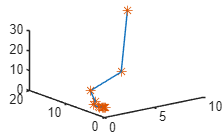

clf
warning('off','all')
A = [2,1,-1;1,2,-1;-1,-1,4];
b = [1;2;9];
x0 = [10;20;30];
xa = x0;

for i = 1:10
    g = A*x0-b;
    alpha = (g'*g)/(g'*(A*g));
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if (errnorm <= 0.001)
        break   
    end
end

plot3(xa(1,:),xa(2,:),xa(3,:))
hold on
plot3(xa(1,:),xa(2,:),xa(3,:),'*')

xa

xa =    10.0000    7.2746    1.1155    1.1128    0.2327    0.5361    0.4820    0.7202    0.7452    0.8684    0.8845
   20.0000   14.5493    6.6822    5.2793    3.5129    3.0709    2.5505    2.4130    2.2212    2.1753    2.0951
   30.0000    5.4718    7.9044    3.3604    3.9063    2.9650    3.1919    2.9334    3.0585    2.9635    3.0230


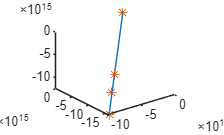

clf
warning('off','all')
A = [11,2,1;2,4,-1;1,-1,6];
b = [12,1,7];
x0 = [2;21;4];
xa = x0;

for i=1:10
    g = A*x0-b;
    alpha = (g'*g)/(g'*(A*g));
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if (errnorm < 0.001)
        break
    end
end
 
plot3(xa(1,:),xa(2,:),xa(3,:))
hold on
plot3(xa(1,:),xa(2,:),xa(3,:),'*')

xa

xa = 1.0e+16 *

    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.5957   -0.9710   -0.7663       NaN       NaN       NaN       NaN       NaN       NaN
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.9710   -1.5828   -1.2491       NaN       NaN       NaN       NaN       NaN       NaN
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.7663   -1.2491   -0.9857       NaN       NaN       NaN       NaN       NaN       NaN


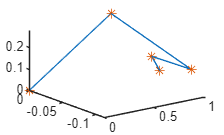

clf
clear
A = [3,0,1;0,4,2;1,2,3];
b = [3;0;1];
x0 = [0;0;0];

xa = x0;

for i = 1:4
    g = A*x0-b;
    alpha = (g'*g)/(g'*(A*g));
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if (errnorm <= 0.001)
        break
    end
end

plot3(xa(1,:),xa(2,:),xa(3,:))
hold on
plot3(xa(1,:),xa(2,:),xa(3,:),'*');


xa

xa =          0    0.8333    0.8790    0.9720    0.9658
         0         0   -0.1143   -0.0407   -0.0543
         0    0.2778    0.1406    0.1103    0.0582


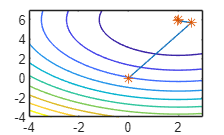

clf
clear
clc

x1 = -4:.25:3;
x2 = -4:.25:7;

[X1,X2] = meshgrid(x1,x2);
Z = 4.*X1.^2 + 3.*X2.^2 - 16*X1 -36*X2 + 25;
contour(X1,X2,Z,10)

A = [8,0;0,6];
b = [16;36];
x0 = [0;0];
xa = x0;

for i = 1:10
    g = A*x0-b;
    alpha = (g'*g)/(g'*(A*g));
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if (errnorm <= 0.001)
        break
    end
end
hold on
plot(xa(1,:),xa(2,:))
hold on
plot(xa(1,:),xa(2,:),'*')

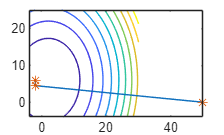

clf
clear
clc

x1 = -4:.25:30;
x2 = -4:.25:25;

[X1,X2] = meshgrid(x1,x2);

Z = 4.*X1.^2 + 3.*X2.^2 - 16*X1 -36*X2 + 25;
contour(X1,X2,Z,10)

A = [8,0;0,6];
b = [-16;36];
x0 = [50;0];
xa = x0;

for i = 1:10
    g = A*x0-b;
    alpha = (g'*g)/(g'*(A*g));
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if (errnorm <= 0.001)
        break
    end
end

hold on
plot(xa(1,:),xa(2,:))
hold on
plot(xa(1,:),xa(2,:),'*')

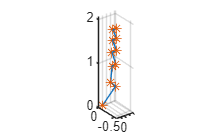

clf
clear
clc

A = [12,0,2;0,16,4;2,4,2];
b = [3;0;3];
x0 = [0;0;0];

xa = x0;
for i = 1:10
    g = A*x0-b;
    alpha = (g'*g)/(g'*(A*g));
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if (errnorm <= 0.001)
        break
    end
end

plot3(xa(1,:),xa(2,:),xa(3,:));
hold on
plot3(xa(1,:),xa(2,:),xa(3,:),'*');
grid on
hold off

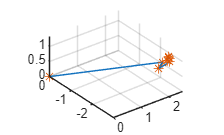

clf 
clear
clc

A = [18,0,0;0,10,0;0,0,6];
b = [36;-30;8];
x0 = [0;0;0];

xa = x0;

for i = 1:10
    g = A*x0-b;
    alpha = (g'*g)/(g'*(A*g));
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if errnorm <= 0.001
        break
    end
end

plot3(xa(1,:),xa(2,:),xa(3,:));
hold on
plot3(xa(1,:),xa(2,:),xa(3,:),'*');
grid on
hold off
axis equal

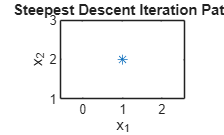

clf 
clear
clc
A = randi([0,5],5); 
x0 = [1;2;3;4;5]; 
b = A*x0; 
xa = x0; 

for i = 1:10 
    g = A*x0 - b; 
    alpha = (g'*g) / (g'*(A*g)); 
    xn = x0 - alpha*g; 
    xa = [xa xn]; 
    x0 = xn; 
    errnorm = norm(A*xn - b, 2); 
    if (errnorm <= 0.001) 
        break 
    end 
end 

figure;
plot(xa(1,:), xa(2,:),'*') 
axis equal
xlabel('x_1'); 
ylabel('x_2');
title('Steepest Descent Iteration Path')

clc
clear

A = [9,2;2,9];
n = size(A,1);
D = zeros(n);
D(:,1) = [1;0];

for k = 2:n

    v = zeros(n,1);
    v(k) = 1;

    for j = 1:k-1
        beta = (D(:,j)'*A*v)/(D(:,j)'*A*D(:,j));
        v = v - beta*D(:,j);
    end

    D(:,k) = v;

end

disp("A-Conjugate Directions")

A-Conjugate Directions


disp(D)

    1.0000   -0.2222
         0    1.0000



clc
clear

A = [1,2,3;4,5,6;7,8,9];
n = size(A,1);
D = zeros(n);

D(:,1) = [1;0;0];

for k = 2:n
    v = zeros(n,1);
    v(k) = 1;

    for j = 1:k-1
        beta = (D(:,j)'*A*v)/(D(:,j)'*A*D(:,j));
        v = v - beta*D(:,j);
    end
    D(:,k) = v;
end

disp(D)

     1    -2     1
     0     1    -2
     0     0     1



clc
clear

A = [2,1,-1;1,2,-1;-1,-1,4];
b = [1;2;9];
x0 = [0;0;0];

r0 = b - A*x0;
d0 = r0;

for i = 1:10000
    Ad = A*d0;
    alpha = (r0'*r0)/(d0'*Ad);
    x = x0 + alpha*d0;
    r = r0 - alpha*Ad;
    
    errnorm = norm(r,2);
    if errnorm <= 1e-10
        break
    end
    beta = (r'*r)/(r0'*r0);
    d0 = r + beta*d0;
    r0 = r;
    x0 = x;
end
x0

x0 =     1.2100
    1.8138
    3.0092


A = [11,2,1;2,4,-1;1,-1,6];
b = [12;1;7];
x0 = [0;0;0];

r0 = b - A*x0;
d0 = r0;

for i = 1:100
    Ad = A*d0;
    alpha = (r0'*r0)/(d0'*Ad);
    x = x0 + alpha*d0;
    r = r0 - alpha*Ad;
    errnorm = norm(r,2);

    if errnorm <= 1e-10
        break
    end

    beta = (r'*r)/(r0'*r0);
    d0 = r + beta*d0;
    r0 = r;
    x0 = x;
end
x0

x0 =     1.0117
   -0.0405
    0.9848


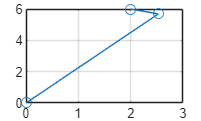

A = [8,0;0,6];
b = [16;36];
x0 = [0;0];

r0 = b - A*x0;
d0 = r0;

history = x0;

for i = 1:1000
    Ad = A*d0;
    alpha = (r0'*r0)/(d0'*Ad);
    x = x0 + alpha*d0;
    r = r0 - alpha*Ad;
    errnorm = norm(r,2);
    history = [history x];

    if (errnorm <= 1e-10)
        break
    end
    beta = (r'*r)/(r0'*r0);
    d0 = r + beta*d0;
    r0 = r;
    x0 = x;
end

figure;
plot(history(1,:),history(2,:),'-o');
hold on
grid on

clf
clear
clc
A = [12,0,2;0,16,4;2,4,2];
b = [3;0;3];
x0 = [0;0;0];
r0 = b - A*x0;
d0 = r0;

history = x0;

for i = 1:1000
    Ad = A*d0;
    alpha = (r0'*r0)/(d0'*Ad);
    x = x0 + alpha*d0;
    r = r0 - alpha*Ad;
    errnorm = norm(r,2);
    history = [history x];
    if errnorm <= 1e-10
        break
    end
    beta = (r'*r)/(r0'*r0);
    d0 = r + beta*d0;
    r0 = r;
    x0 = x;
end

iterations = i

iterations = 3

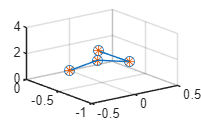

plot3(history(1,:), history(2,:), history(3,:) , '-o')   
hold on
plot3(history(1,:), history(2,:), history(3,:), '*') 
grid on

% Question - 1 
% Lab seven
clf
clear
clc
X = [2,4,5,6,8,11];
Y = [18,12,10,8,7,5];

C = cov(X,Y)

C =    10.0000  -13.4000
  -13.4000   21.2000


R = C(1,2)/(sqrt(C(1,1)).*sqrt(C(2,2)))

R = -0.9203

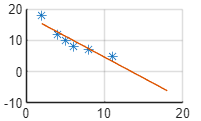


scatter(X,Y,'*');
hold on
grid on

p = polyfit(X,Y,1);
m = p(1);
c = p(2);

xfit = linspace(min(X),max(Y),100);
yfit = m*xfit + c;

plot(xfit,yfit);


% m = sum(X - mean(X)).*(Y - mean(Y))/sum((X - mean(X)).^2);
% c = mean(Y) - m*mean(X);